## Consideraciones

Para el uso de este proyecto se deben poseer las siguientes toolboxs

- Image Processing ToolBox 

- Deep Learning ToolBox

- Computer Vision ToolBox

- Computer Vision Toolbox Model for YOLO v4 Object Detection

- Computer Vision Toolbox Model for Object Keypoint Detection (HRnet)

- MATLAB Support Package for USB Webcams

## Imagen

clear

clear VidPrueba Frame;

%Redes Neuronales
DetectorDePuntos = hrnetObjectKeypointDetector("human-full-body-w32");
DetectorDePuntos.Threshold = 0.6;%YOLO V4
DetectorDeObjetos = yolov4ObjectDetector("csp-darknet53-coco");
Filtro =fspecial("gaussian",6*2,2);

%Carga

%Lectura
Frame = imread("Dataset\Images\012.jpg");
Frame = imfilter(Frame,Filtro);

figure(13); imshow(Frame);
%Procesamiento

%Detección de personas
[Cajas,~,Clases] = detect(DetectorDeObjetos,Frame,"Threshold",0.5);
    
    
if isempty(Cajas)||~prod(~(Cajas(:,1)>=size(Frame,2)),1)||~prod(~(Cajas(:,1)<=1),1)||~prod(~(Cajas(:,2)>=size(Frame,1)),1)||~prod(~(Cajas(:,2)<=1),1)
    error("No hay objetos en esta imagen"); 
end

FrameObjetos = insertObjectAnnotation(Frame,"rectangle",Cajas,Clases,LineWidth=floor(max(size(Frame))*0.01),FontSize=36);

%Filtrado
Cajas = Cajas(Clases=="person",:);
Clases = Clases(Clases=="person");

%Solo la primera detección 
if (length(Clases)>1)
    Cajas = Cajas(2,:);
    Clases = Clases(2);
end  

%Inserción
FramePersonas = insertObjectAnnotation(Frame,"rectangle",Cajas,Clases,LineWidth=floor(max(size(Frame))*0.01),FontSize=36);
    
if isempty(Cajas)||~prod(~(Cajas(:,1)>=size(Frame,2)),1)||~prod(~(Cajas(:,1)<=1),1)||~prod(~(Cajas(:,2)>=size(Frame,1)),1)||~prod(~(Cajas(:,2)<=1),1)
    error("No hay objetos en esta imagen"); 
end

%Detección de puntos
[Puntos,~,Validacion] = detect(DetectorDePuntos,FramePersonas,Cajas);
    
%Inserción
%Orden 1 Nariz, OjoDerecho 2, Ojo Izquierdo 3, Oreja derecha 4, Oreja
%izquierda 5

FramePuntos = insertObjectKeypoints(FramePersonas,Puntos(:,:,:),KeypointColor="yellow",KeypointSize=floor(max(size(FramePersonas))*0.01));
%FramePuntos = insertObjectKeypoints(FramePuntos,(sum(Puntos([6 12],:))*0.5+sum(Puntos([7 13],:))*0.5)/2,KeypointColor="green",KeypointSize=floor(max(size(FramePersonas))*0.01));
%Correción de puntos

%Cuello 19
Cuello=sum(Puntos([6 7],:,:))*0.5;

%Solo Cabeza 18
%Cabeza= sum(Puntos(1:5,:,:))/5;
Cabeza= (sum(Puntos([2 4],:,:))/2 + sum(Puntos([3 5],:,:))/2)/2;

%Cabeza= sum(Puntos(1:2,:,:))/5;
%Entre pierna 21
EntrePierna= sum(Puntos([12 13],:,:))*0.5;

%Pecho Medio 20
PechoMedio= (Cuello+EntrePierna)/2;

%Nuevos Puntos
NewPuntos = [Puntos; Cabeza;Cuello;PechoMedio;EntrePierna];

%Viejos Puntos
%No necesitamos ojos (1,2), orejas(3,4) ni nariz (5)
New2Puntos = NewPuntos(6:end,:,:);


%Nuevo Frame Puntos
NewFramePuntos = insertObjectKeypoints(FramePersonas,NewPuntos, ...
    KeypointColor="red",KeypointSize=floor(max(size(FramePersonas))*0.01));

New2FramePuntos = insertObjectKeypoints(FramePersonas,New2Puntos, ...
    KeypointColor="red",KeypointSize=floor(max(size(FramePersonas))*0.01));

%Esqueleto
FrameEsqueleto = insertObjectKeypoints(FramePersonas,Puntos,KeypointColor="yellow",KeypointSize=floor(max(size(FramePersonas))*0.01),Connections=DetectorDePuntos.KeypointConnections,ConnectionColor="blue", LineWidth=floor(max(size(FramePersonas))*0.01));

%Correción de conecciones
%Cuello-Cabeza (19-18)
NewKeyPointsConections = [DetectorDePuntos.KeypointConnections; [19 18]];

%Hombros-Cuello (6-19) (7-19)
NewKeyPointsConections = [NewKeyPointsConections; [6 19];[7 19]];

%Cuello-Pecho Medio (19-20)
NewKeyPointsConections = [NewKeyPointsConections; [19 20]];

%Pecho Medio- EntrePierna (20 - 21)
NewKeyPointsConections = [NewKeyPointsConections;[20 21]];

%Muslos- EntrePierna (12 - 21) (13 - 21)
NewKeyPointsConections = [NewKeyPointsConections; [12 21];[13 21]];

%Viejas conecciones
%No necesitamos conecciones que involucren ojos, orjas o nariz
New2KeyPointsConections = NewKeyPointsConections(7:end,:)-5;
New2KeyPointsConections = New2KeyPointsConections([1:4,7:end], :);
%Nuevo Esqueleto
NewFrameEsqueleto = insertObjectKeypoints(FramePersonas,NewPuntos,KeypointColor="red",KeypointSize=floor(max(size(FramePersonas))*0.01),Connections=NewKeyPointsConections,ConnectionColor="yellow", LineWidth=floor(max(size(FramePersonas))*0.01));
New2FrameEsqueleto = insertObjectKeypoints(FramePersonas,New2Puntos,KeypointColor="red",KeypointSize=floor(max(size(FramePersonas))*0.01),Connections=New2KeyPointsConections,ConnectionColor="yellow", LineWidth=floor(max(size(FramePersonas))*0.01));
%Muestra
if isempty(Validacion)
   error("Error de validación");
end
FramePuntos = insertObjectKeypoints(FramePuntos,New2Puntos([1 5],:,:),KeypointColor="blue",KeypointSize=floor(max(size(FramePersonas))*0.01));     
figure(15); montage({FramePuntos,New2FramePuntos, FrameEsqueleto});

figure(16); montage({NewFramePuntos,NewFrameEsqueleto,New2FrameEsqueleto});

%Nuevo Orden
% Cols: X, Rows: Y
% De arriba hacia abajo
%De Izquierda a derecha

%Correción de Y
New2Puntos(:,2,:) = size(Frame,1)-New2Puntos(:,2,:);
%Aplicación RULA (Usar New2Puntos)

Puntuacion=CalculaRULA(New2Puntos);
disp(['La puntuación RULA es: ', num2str(Puntuacion)]);
Veredicto=Resultado(Puntuacion);
disp(['El resultado es:', Veredicto]);
figure(17); imshow(New2FrameEsqueleto); title("La puntación RULA es " + num2str(Puntuacion) + ". Con resultado " + Veredicto );

## Inserción de la cámara Web

clear;

%Redes Neuronales
DetectorDeObjetos = yolov4ObjectDetector("tiny-yolov4-coco");
DetectorDePuntos = hrnetObjectKeypointDetector("human-full-body-w32");
DetectorDePuntos.Threshold = 0.6;
Filtro = fspecial("gaussian",6*2,2);
Encontrado=0;

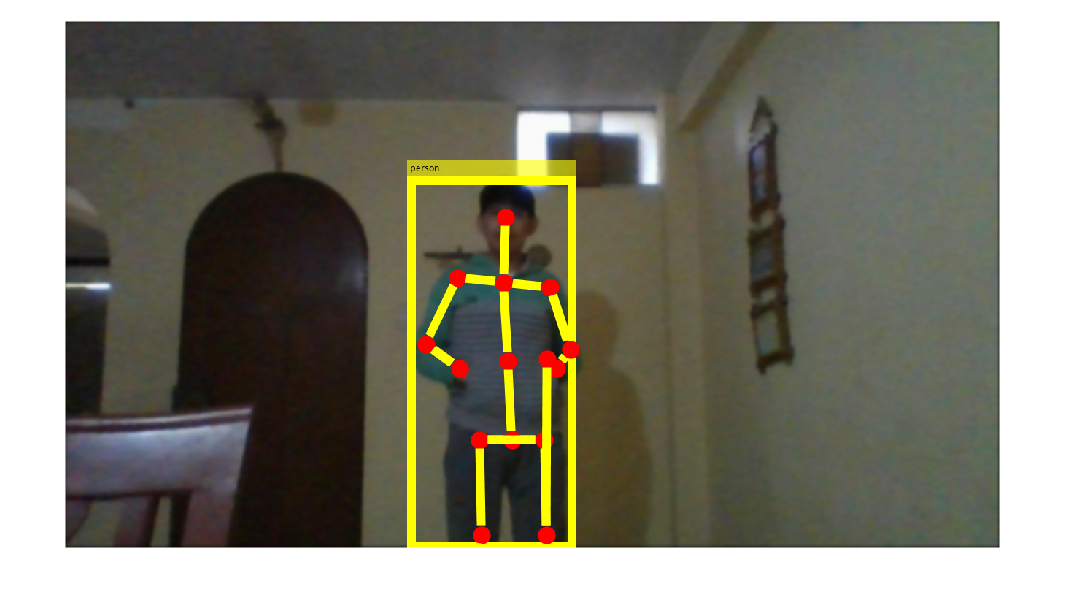


%Activar cámara
cam = webcam;

%Tiempo de captura (segundos)
%Tiempo = 30; %Fps=15 average;

%Frames en total
TotalFrames = 50;

for  i = 1:TotalFrames
    
    %Obtención de datos
    Frame = fliplr(snapshot(cam));
   
    %Preprocesamiento
    Frame = imfilter(Frame,Filtro);
    %Procesamiento

    %Detección de personas
    [Cajas,~,Clases] = detect(DetectorDeObjetos,Frame,"Threshold",0.5);
    
    %isempty(Cajas)||Cajas(1)>=size(Frame,1)||Cajas(1)<=1||Cajas(2)>=size(Frame,2)||Cajas(2)<=1||Cajas(3)>=size(Frame,1)|| Cajas(4)>=size(Frame,2)
    
    if isempty(Cajas)||~prod(~(Cajas(:,1)>=size(Frame,2)),1)||~prod(~(Cajas(:,1)<=1),1)||~prod(~(Cajas(:,2)>=size(Frame,1)),1)||~prod(~(Cajas(:,2)<=1),1)
      figure(20); imshow(Frame); title("Enfoque mejor su cámara"); Encontrado=0; continue;
    end

    FrameObjetos = insertObjectAnnotation(Frame,"rectangle",Cajas,Clases,LineWidth=floor(max(size(Frame))*0.01),FontSize=floor(max(size(Frame))*0.01));

    %Filtrado
    Cajas = Cajas(Clases=="person",:);
    Clases = Clases(Clases=="person");

    %La detección más grande 
    if (length(Clases)>1)
        indx = find(prod(Cajas')==max(prod(Cajas')))
        Cajas = Cajas(indx,:);
        Clases = Clases(indx);
    end  
   
    %Inserción
    FramePersonas = insertObjectAnnotation(Frame,"rectangle",Cajas,Clases,LineWidth=floor(max(size(Frame))*0.01),FontSize=floor(max(size(Frame))*0.01));
    %isempty(Cajas)||Cajas(1)>=size(Frame,1)||Cajas(1)<=1||Cajas(2)>=size(Frame,2)||Cajas(2)<=1||Cajas(3)>=size(Frame,1)|| Cajas(4)>=size(Frame,2)

    if isempty(Cajas)||~prod(~(Cajas(:,1)>=size(Frame,2)),1)||~prod(~(Cajas(:,1)<=1),1)||~prod(~(Cajas(:,2)>=size(Frame,1)),1)||~prod(~(Cajas(:,2)<=1),1)
        figure(20); imshow(Frame); title("Enfoque mejor su cámara"); Encontrado=0; continue;
    end

    %Detección de puntos
    [Puntos,~,Validacion] = detect(DetectorDePuntos,FramePersonas,Cajas);

    if isempty(Validacion)
        figure(20); imshow(Frame); title("Enfoque mejor su cámara"); Encontrado=0; continue;
    end
    
    %Inserción
    %Orden 1 Nariz, OjoDerecho 2, Ojo Izquierdo 3, Oreja derecha 4, Oreja
    %izquierda 5

    FramePuntos = insertObjectKeypoints(FramePersonas,Puntos(:,:,:),KeypointColor="yellow",KeypointSize=floor(max(size(FramePersonas))*0.01));
    %FramePuntos = insertObjectKeypoints(FramePuntos,(sum(Puntos([6 12],:))*0.5+sum(Puntos([7 13],:))*0.5)/2,KeypointColor="green",KeypointSize=floor(max(size(FramePersonas))*0.01));
    %Correción de puntos

    %Cuello 19
    Cuello=sum(Puntos([6 7],:,:))*0.5;

    %Solo Cabeza 18
    %Cabeza= sum(Puntos(1:5,:,:))/5;
    Cabeza= (sum(Puntos([2 4],:,:))/2 + sum(Puntos([3 5],:,:))/2)/2;

    %Cabeza= sum(Puntos(1:2,:,:))/5;
    %Entre pierna 21
    EntrePierna= sum(Puntos([12 13],:,:))*0.5;

    %Pecho Medio 20
    PechoMedio= (Cuello+EntrePierna)/2;

    %Nuevos Puntos
    NewPuntos = [Puntos; Cabeza;Cuello;PechoMedio;EntrePierna];

    %Viejos Puntos
    %No necesitamos ojos (1,2), orejas(3,4) ni nariz (5)
    New2Puntos = NewPuntos(6:end,:,:);


    %Nuevo Frame Puntos
    NewFramePuntos = insertObjectKeypoints(FramePersonas,NewPuntos, ...
    KeypointColor="red",KeypointSize=floor(max(size(FramePersonas))*0.01));

    New2FramePuntos = insertObjectKeypoints(FramePersonas,New2Puntos, ...
    KeypointColor="red",KeypointSize=floor(max(size(FramePersonas))*0.01));

    %Esqueleto
    FrameEsqueleto = insertObjectKeypoints(FramePersonas,Puntos,KeypointColor="yellow",KeypointSize=floor(max(size(FramePersonas))*0.01),Connections=DetectorDePuntos.KeypointConnections,ConnectionColor="blue", LineWidth=floor(max(size(FramePersonas))*0.01));

    %Correción de conecciones
    %Cuello-Cabeza (19-18)
    NewKeyPointsConections = [DetectorDePuntos.KeypointConnections; [19 18]];

    %Hombros-Cuello (6-19) (7-19)
    NewKeyPointsConections = [NewKeyPointsConections; [6 19];[7 19]];

    %Cuello-Pecho Medio (19-20)
    NewKeyPointsConections = [NewKeyPointsConections; [19 20]];

    %Pecho Medio- EntrePierna (20 - 21)
    NewKeyPointsConections = [NewKeyPointsConections;[20 21]];

    %Muslos- EntrePierna (12 - 21) (13 - 21)
    NewKeyPointsConections = [NewKeyPointsConections; [12 21];[13 21]];

    %Viejas conecciones
    %No necesitamos conecciones que involucren ojos, orjas o nariz
    New2KeyPointsConections = NewKeyPointsConections(7:end,:)-5;
    New2KeyPointsConections = New2KeyPointsConections([1:4,7:end], :);
    %Nuevo Esqueleto
    NewFrameEsqueleto = insertObjectKeypoints(FramePersonas,NewPuntos,KeypointColor="red",KeypointSize=floor(max(size(FramePersonas))*0.01),Connections=NewKeyPointsConections,ConnectionColor="yellow", LineWidth=floor(max(size(FramePersonas))*0.01));
    New2FrameEsqueleto = insertObjectKeypoints(FramePersonas,New2Puntos,KeypointColor="red",KeypointSize=floor(max(size(FramePersonas))*0.01),Connections=New2KeyPointsConections,ConnectionColor="yellow", LineWidth=floor(max(size(FramePersonas))*0.01));
    %Muestra
   
    figure(20); imshow(New2FrameEsqueleto);
    pause(1/15);

end

ScoreA = 3

ScoreB = 4

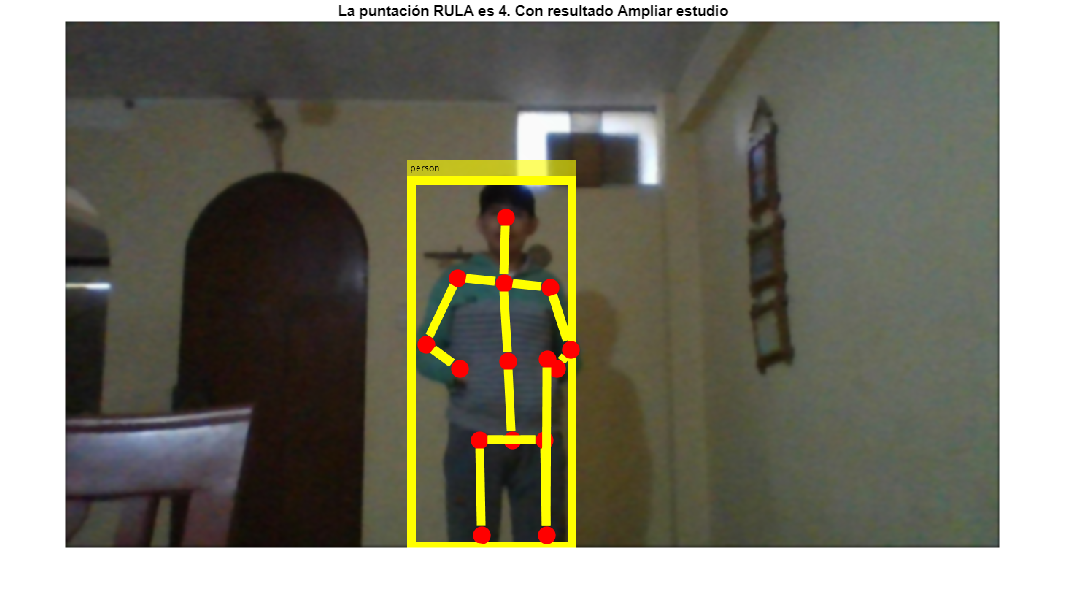

clear cam

%Validar existencia
if exist("New2FramePuntos","var")
    %Validar mejor resultado
    if ~Encontrado 
        Frame = New2FramePuntos;
    end
    
    %Nuevo Orden
    % Cols: X, Rows: Y
    % De arriba hacia abajo
    %De Izquierda a derecha

    %Correción de Y
    New2Puntos(:,2,:) = size(Frame,1)-New2Puntos(:,2,:);

    %Aplicación RULA (Usar New2Puntos)
    Puntuacion=CalculaRULA(New2Puntos);
    Veredicto=Resultado(Puntuacion);
    figure(21); imshow(New2FrameEsqueleto); title("La puntación RULA es " + num2str(Puntuacion) + ". Con resultado " + Veredicto );

else
   figure(21); imshow(Frame); title("Tiempo de espera culminado... Intente de nuevo");
end